# Lab 7: MNIST Digit Classification with kNN and SVMs

Submission due Wednesday, October 17th, 1.30pm.

## Dataset

In this lab, we will be using the MNIST Dataset, which can be downloaded from [http://yann.lecun.com/exdb/mnist/.](http://yann.lecun.com/exdb/mnist/.)

The MNIST Dataset is a set of black and white photos of handwritted digits with their corresponding labels from 0 to 9. 

 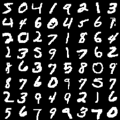

There are four files on this website - 

[`train-images-idx3-ubyte.gz`](http://yann.lecun.com/exdb/mnist/train-images-idx3-ubyte.gz)`:  training set images (9912422 bytes)` 

[`train-labels-idx1-ubyte.gz`](http://yann.lecun.com/exdb/mnist/train-labels-idx1-ubyte.gz)`:  training set labels (28881 bytes)` 

[`t10k-images-idx3-ubyte.gz`](http://yann.lecun.com/exdb/mnist/t10k-images-idx3-ubyte.gz)`:   test set images (1648877 bytes)` 

[`t10k-labels-idx1-ubyte.gz`](http://yann.lecun.com/exdb/mnist/t10k-labels-idx1-ubyte.gz)`:   test set labels (4542 bytes)`

You should download these four files and use the files `loadMNISTImages.m` and `loadMNISTLabels.m` to load these into MATLAB arrays.

%INITIALIZE
clear
close all

%LOAD DATA
train_img = loadMNISTImages('train-images-idx3-ubyte');
train_lbl = loadMNISTLabels('train-labels-idx1-ubyte');
test_img = loadMNISTImages('t10k-images-idx3-ubyte');
test_lbl = loadMNISTLabels('t10k-labels-idx1-ubyte');

## Problem Statement

The goal of this lab is to perform classification on the MNIST dataset, where the input is an image of a digit and your prediction is a number between 0 to 9.

We will also have a competition for this lab. Extra credit will be awarded for each student who achieves the best results across the class for either the KNN method or the SVM method. There are two extra credits up for grabs.

The basic method for this lab is as follows - 

- Train and find the PCA dimensions for the training data.

- Project both the training and testing datasets using these PCA bases.

- Explore the performance of KNN and SVMs by varying the number of PCA bases being projected on.

%normalize
train_mean = mean(train_img, 2);
test_mean = mean(test_img, 2);

train_mean_repmat = repmat(train_mean,1,60000);
train_center = train_img - train_mean_repmat;
test_mean_repmat = repmat(train_mean,1,10000);
test_center = test_img - test_mean_repmat;

%train projection
dimension = 10;

train_corr = train_center * train_center';
[e_vec_train, e_val_train] = eigs(train_corr,dimension);

e_vec_train = real(e_vec_train);
e_val_train = abs(e_val_train);

B_train = e_vec_train;
W_train = pinv(B_train) * double(train_center);
train_approx = B_train * W_train;

%test projection
B_test = e_vec_train;
W_test = pinv(B_test) * double(test_center);
test_approx = B_test * W_test;


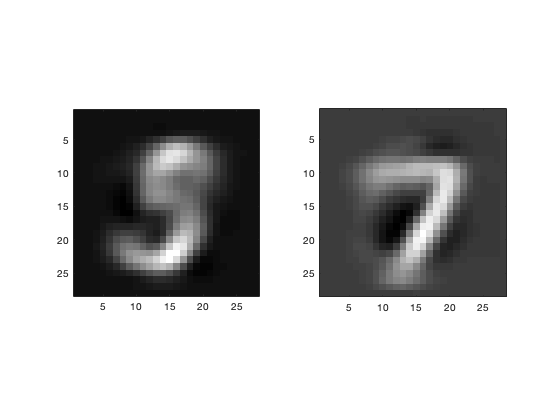

%plot
figure(1)
%train img_1
image_approx_plot1 = reshape(train_approx(:,1)+ train_mean,28,28);
subplot(1,2,1)
imagesc(image_approx_plot1), axis image, colormap gray;
%test img_1
image_approx_plot2 = reshape(test_approx(:,1)+ train_mean,28,28);
subplot(1,2,2)
imagesc(image_approx_plot2), axis image, colormap gray;

## 1. KNN

Implement the K-nearest neighbor algorithm for the 10 classes that you have. Find these 10 clusters using your training data, and then classify your testing data based on each test image's distance to your 10 trained clusters. Report your result for the different number of PCA bases being projected on.

number_k = [5,7,9,11,13,15,17];
error_matrix = [];
accuracy_matrix = [];

%KNN function
for j = 1:7
   predict_label = zeros(size(W_test,2),1);
   for i = 1:size(W_test,2)
      diff = W_test(:,i)-W_train(:,:);
      dist = sqrt(sum(diff.^2,1));
      [min,idx] = mink(dist,number_k(j));
      labels = train_lbl(idx);
      predict_label(i) = mode(labels);
   end
   error = length(test_lbl((test_lbl ~= predict_label)));
   accuracy = error/size(W_test,2);
   error_matrix = [error_matrix, error];
   accuracy_matrix = [accuracy_matrix, accuracy];
end 

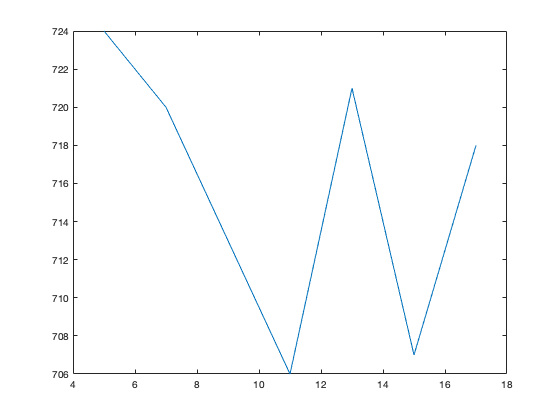

%plot
figure(2)
plot(number_k,error_matrix);

%train projection
dimension1 = 100;

train_corr = train_center * train_center';
[e_vec_train1, e_val_train1] = eigs(train_corr,dimension1);

e_vec_train1 = real(e_vec_train1);
e_val_train1 = abs(e_val_train1);

B_train1 = e_vec_train1;
W_train1 = pinv(B_train1) * double(train_center);
train_approx1 = B_train1 * W_train1;

%test projection
B_test1 = e_vec_train1;
W_test1 = pinv(B_test1) * double(test_center);
test_approx1 = B_test1 * W_test1;

number_k1 = [10,11,12,13,14,15];
error_matrix1 = [];
accuracy_matrix1 = [];

%KNN function
for j = 1:6
   predict_label1 = zeros(size(W_test1,2),1);
   for i = 1:size(W_test1,2)
      diff = W_test1(:,i)-W_train1(:,:);
      dist = sqrt(sum(diff.^2,1));
      [min,idx] = mink(dist,number_k1(j));
      labels1 = train_lbl(idx);
      predict_label1(i) = mode(labels1);
   end
   error1 = length(test_lbl((test_lbl ~= predict_label1)));
   accuracy1 = error1/size(W_test1,2);
   error_matrix1 = [error_matrix1, error1];
   accuracy_matrix1 = [accuracy_matrix1, accuracy1];
end  

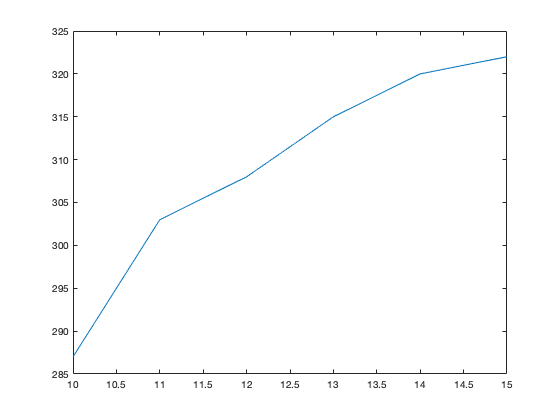

%plot
figure(3)
plot(number_k1,error_matrix1);

number_k2 = [7,8,9];
error_matrix2 = [];
accuracy_matrix2 = [];

%KNN function
for j = 1:3
   predict_label2 = zeros(size(W_test1,2),1);
   for i = 1:size(W_test1,2)
      diff = W_test1(:,i)-W_train1(:,:);
      dist = sqrt(sum(diff.^2,1));
      [min,idx] = mink(dist,number_k2(j));
      labels2 = train_lbl(idx);
      predict_label2(i) = mode(labels2);
   end
   error2 = length(test_lbl((test_lbl ~= predict_label2)));
   accuracy2 = error2/size(W_test1,2);
   error_matrix2 = [error_matrix2, error2];
   accuracy_matrix2 = [accuracy_matrix2, accuracy2];
end

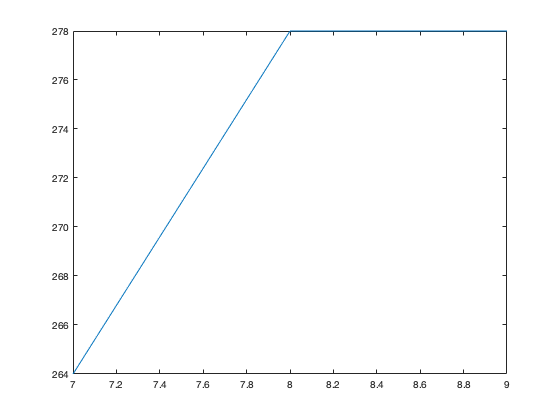

%plot
figure(4)
plot(number_k2,error_matrix2);

number_k3 = [4,5,6];
error_matrix3 = [];
accuracy_matrix3 = [];

%KNN function
for j = 1:3
   predict_label3 = zeros(size(W_test1,2),1);
   for i = 1:size(W_test1,2)
      diff = W_test1(:,i)-W_train1(:,:);
      dist = sqrt(sum(diff.^2,1));
      [min,idx] = mink(dist,number_k3(j));
      labels3 = train_lbl(idx);
      predict_label3(i) = mode(labels3);
   end
   error3 = length(test_lbl((test_lbl ~= predict_label3)));
   accuracy3 = error3/size(W_test1,2);
   error_matrix3 = [error_matrix3, error3];
   accuracy_matrix3 = [accuracy_matrix3, accuracy3];
end

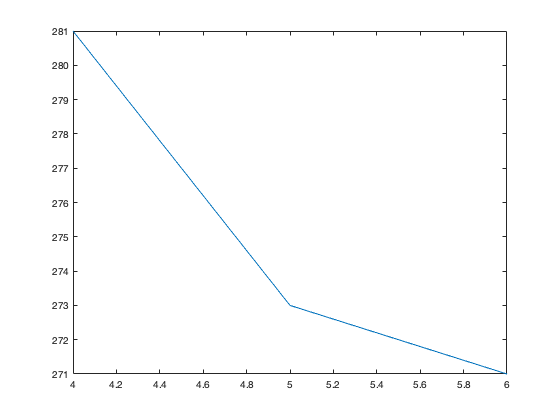

%plot
figure(4)
plot(number_k3,error_matrix3);

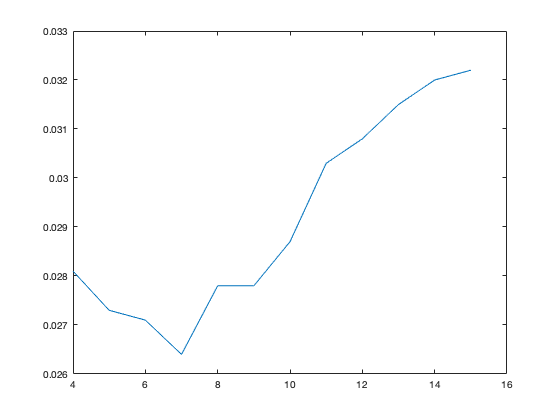

%plot in total
figure(5)
accuracy_total = [accuracy_matrix3, accuracy_matrix2,accuracy_matrix1];
number_k_total = [number_k3,number_k2,number_k1];
plot(number_k_total,accuracy_total)

## `the best result is using 7 neighbourhood, and 100 weights. the best accuracy is 97.36%, with 2.64% error`

## 2. SVM

Use the MATLAB `svm` function to do 10-class classification of the MNIST Data. Examples can be found at [https://www.mathworks.com/help/stats/support-vector-machine-classification.html](https://www.mathworks.com/help/stats/support-vector-machine-classification.html) for Matlab. For Python you can use scikit-learn: [http://scikit- learn.org/stable/modules/svm.html](http://scikit- learn.org/stable/modules/svm.html). Play with different C values and kernel functions and see how they influence your result. Report your best accuracy and settings include the dimension, C value, and kernel function you used. 									

Submit all your code and a **writeup as PDF** reporting the parameters that gave you your best performance. **Do not include the data directory**. 

boxconstraint = [5,15,50];


error_SVM_g = [];
accuracy_SVM_g = [];
for i = 1:3
    t = templateSVM('BoxConstraint',boxconstraint(i),'Standardize',true,'KernelFunction','gaussian');
    SVMModel = fitcecoc(W_train',train_lbl,'Learners',t);
    SVM_label = predict(SVMModel,W_test');
    error_SVM = length(test_lbl((test_lbl ~= SVM_label)));
    accuracy_SVM = error_SVM/size(W_test,2);
    error_SVM_g = [error_SVM_g,error_SVM];
    accuracy_SVM_g = [accuracy_SVM_g,accuracy_SVM];
end    


error_SVM_l = [];
accuracy_SVM_l = [];
for i = 1:3
    t = templateSVM('BoxConstraint',boxconstraint(i),'Standardize',true,'KernelFunction','linear');
    SVMModel = fitcecoc(W_train',train_lbl,'Learners',t);
    SVM_label = predict(SVMModel,W_test');
    error_SVM = length(test_lbl((test_lbl ~= SVM_label)));
    accuracy_SVM = error_SVM/size(W_test,2);
    error_SVM_l = [error_SVM_l,error_SVM];
    accuracy_SVM_l = [accuracy_SVM_l,accuracy_SVM];
end     


error_SVM_p = [];
accuracy_SVM_p = [];
for i = 1:2
    t = templateSVM('BoxConstraint',boxconstraint(i),'Standardize',true,'KernelFunction','polynomial');
    SVMModel = fitcecoc(W_train',train_lbl,'Learners',t);
    SVM_label = predict(SVMModel,W_test');
    error_SVM = length(test_lbl((test_lbl ~= SVM_label)));
    accuracy_SVM = error_SVM/size(W_test,2);
    error_SVM_p = [error_SVM_p,error_SVM];
    accuracy_SVM_p = [accuracy_SVM_p,accuracy_SVM];
end   

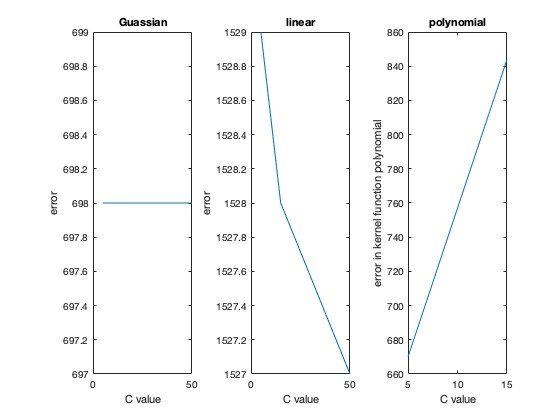

%plot in total
figure(6)
subplot(1,3,1)
plot(boxconstraint,error_SVM_g);
ylabel('error');
xlabel('C value');
title('Guassian');
subplot(1,3,2)
plot(boxconstraint,error_SVM_l);
ylabel('error');
xlabel('C value');
title('linear');
subplot(1,3,3)
plot(boxconstraint(1:2),error_SVM_p);
ylabel('error in kernel function polynomial');
xlabel('C value');
title('polynomial');

## **After a whole night running, the best SVM result is C=5, kernel function is 'polynomial', the error rate is 6.7%, so the accuracy is 93.3%**